
motorname = "Motor0 "

motorname = "Motor0 "

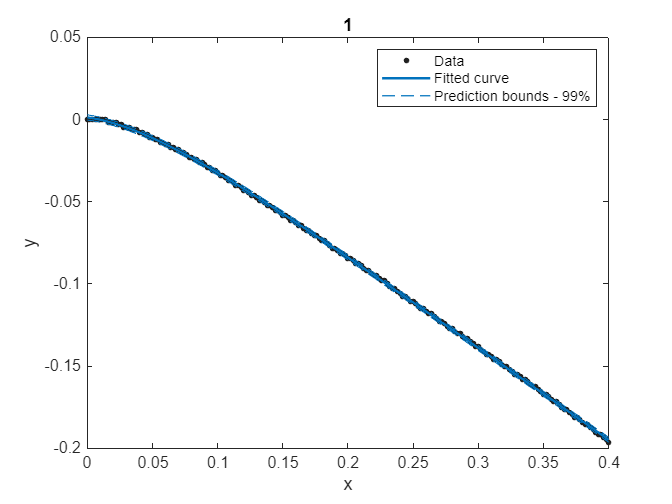

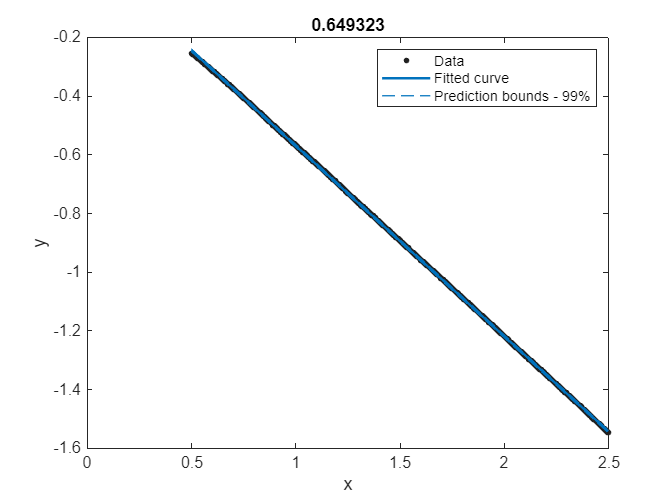

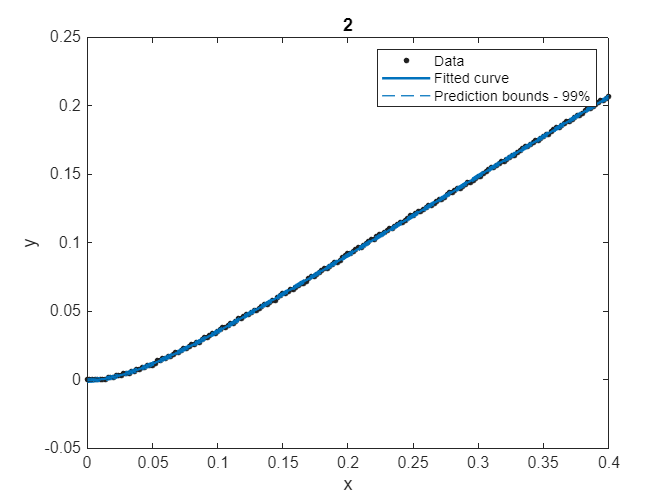

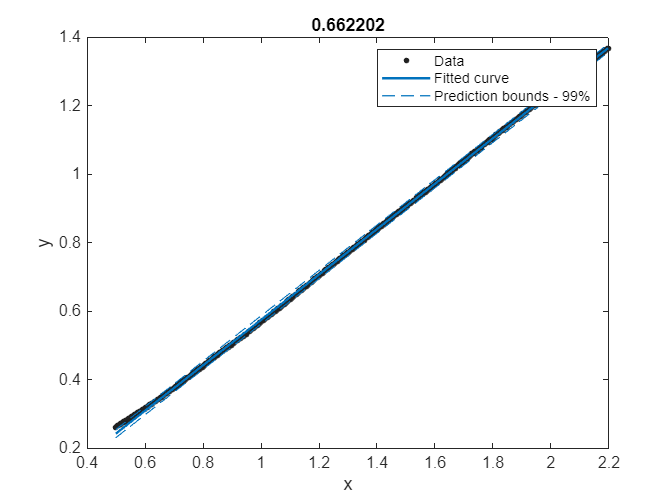

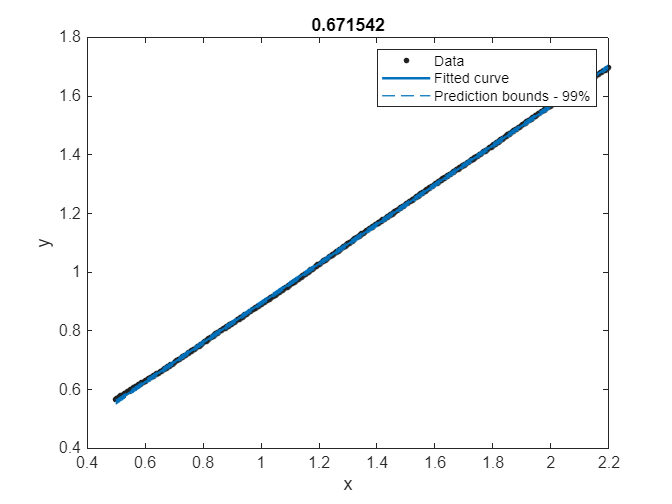

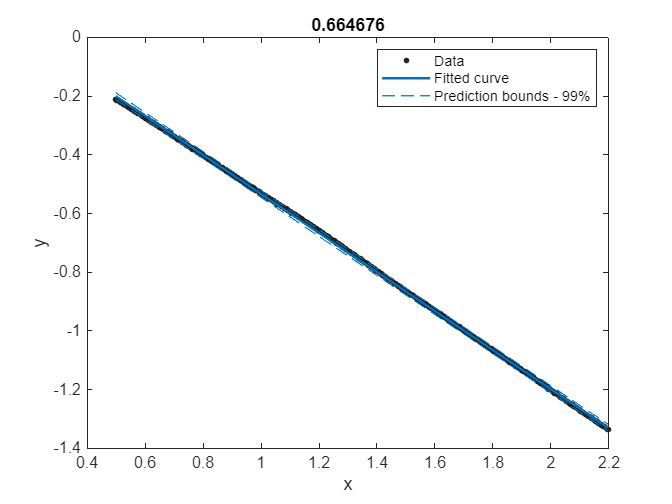

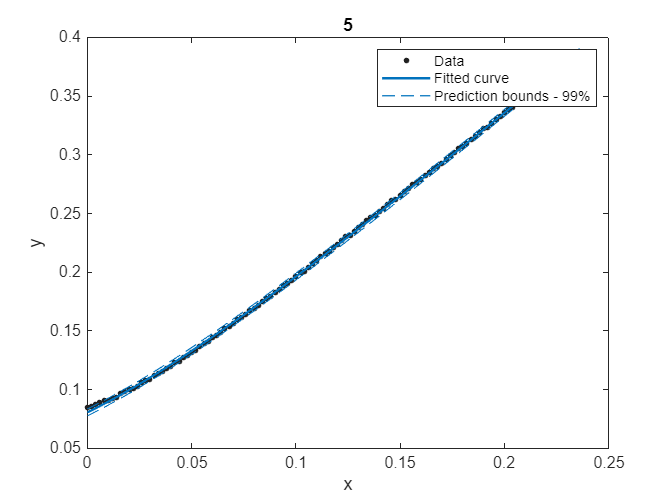

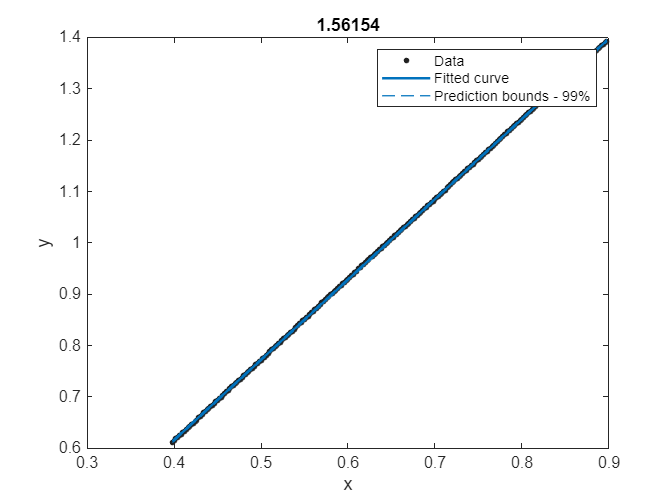

La = 0.18e-3;
Km = 7.68e-3; % V/(rad/s)
Ra = 2.6;

filelist = ["data_04-Mar-2025_10.mat","data_04-Mar-2025_14-46-39.mat","data_04-Mar-2025_14-48-35.mat","data_04-Mar-2025_14-49-36.mat","data_04-Mar-2025_15-02-19.mat","data_04-Mar-2025_15-04-28.mat","data_04-Mar-2025_15-06-09.mat","data_04-Mar-2025_15-07-04.mat","data_04-Mar-2025_15-13-13.mat","data_04-Mar-2025_15-16-08.mat","data_04-Mar-2025_15-27-48.mat","data_04-Mar-2025_15-29-27.mat","data_04-Mar-2025_15-30-56.mat","data_04-Mar-2025_15-31-20.mat","data_04-Mar-2025_15-33-26.mat","data_04-Mar-2025_15-34-00.mat","data_04-Mar-2025_15-37-14.mat","data_04-Mar-2025_15-39-43.mat","data_04-Mar-2025_15-42-28.mat","data_04-Mar-2025_15-43-46.mat","data_04-Mar-2025_15-47-42.mat","data_04-Mar-2025_15-49-10.mat","data_04-Mar-2025_15-51-30.mat","data_04-Mar-2025_15-52-22.mat","data_04-Mar-2025_15-54-09.mat","data_04-Mar-2025_15-57-04.mat","data_04-Mar-2025_16-08-14.mat","data_04-Mar-2025_16-11-22.mat","data_04-Mar-2025_16-14-18.mat","data_04-Mar-2025_16-16-56.mat","data_04-Mar-2025_16-18-18.mat","data_04-Mar-2025_16-21-30.mat","data_04-Mar-2025_16-24-24.mat","data_04-Mar-2025_16-29-52.mat","data_04-Mar-2025_16-55-40.mat","data_04-Mar-2025_17-24-37.mat","data_04-Mar-2025_17-40-31.mat","data_04-Mar-2025_17-41-21.mat","data_04-Mar-2025_17-43-22.mat","data_04-Mar-2025_17-50-09.mat","data_04-Mar-2025_17-51-54.mat","data_04-Mar-2025_17-54-59.mat","data_04-Mar-2025_17-57-30.mat","data_04-Mar-2025_17-57-53.mat","data_04-Mar-2025_18-00-51.mat","data_04-Mar-2025_18-01-13.mat","data_04-Mar-2025_18-03-09.mat","data_04-Mar-2025_18-06-22.mat","data_04-Mar-2025_18-07-09.mat","data_04-Mar-2025_18-09-15.mat","data_04-Mar-2025_18-10-36.mat","data_04-Mar-2025_18-11-39.mat","data_04-Mar-2025_18-12-13.mat","data_04-Mar-2025_18-13-24.mat","data_04-Mar-2025_18-14-40.mat","data_04-Mar-2025_18-15-39.mat","data_04-Mar-2025_18-16-46.mat","data_04-Mar-2025_18-17-52.mat","data_04-Mar-2025_18-18-49.mat"];
voltages = [0.5 0.5 0.5 0.5 1 1 1 1.5 1.5 2 2 3];

% disco vars
file_index = [ 47 48 49 50 51 52 53 54 55 56 57 58];
t_start_disco = 0.5*ones(12) + [0 0 0 0 0.014 0.012 0.006 0 0 0 0 0 ]';
t_end_disco = [0.9 , 0.9 ,0.9 , 0.9 , 0.75 , 0.75 , 0.75, 0.75 , 0.75, 0.75,  0.75, 0.75];
enable_disco = [ true true false  false true true true true true true true true];
discoShape = fittype( 'a*(x-d)+a*tau*(exp(-(x-d)/tau)-1)+b', 'independent', 'x', 'dependent', 'y' );
discoOpts = fitoptions( 'Method', 'NonlinearLeastSquares' );
discoOpts.Display = 'Off';
discoOpts.Lower = [-10 -0.05 -0.1 0.001];
discoOpts.StartPoint = [0.655477890177557 0 0 0.05];
discoOpts.Upper = [10 0.05 0 1];
tauDisco = [];
betaDisco = [];

% slope vars
t_start_slope = [1.0, 1.0 , 1.0 , 1.0 , 0.9, 0.7 , 0.7, 0.8 , 0.7, 0.7 , 0.7, 0.65];
t_end_slope = [3.0 , 2.7 , 2.7 , 2.7 , 1.4 , 1.2 , 1.2, 1.1 , 1.0, 0.95,  0.92, 0.8];
enable_slope = [ true true true true true true true true true true true true];
slope = fittype( 'poly1' );
slopeOpts = fitoptions( 'Method', 'LinearLeastSquares' );
omega_l_slope = [];
beta_slope = [];
for i = 1:size(file_index,2)
    t_samp = 0.002;
    n_exp = file_index(i);
    load("lab1/data/"+filelist(n_exp),"data");
    % smartPlotEncVoltage(data,i+"&"+n_exp,true);

    t = data(1,:);
    x = data(2,:);
    %% DISCO
    if enable_disco(i)
    tsd = int32(t_start_disco(i)/t_samp) +1; %start DISCO id
    ted = int32(t_end_disco(i)/t_samp) +1;  %end DISCO id    
    t_focus_disco = t(tsd:ted)-t(tsd);
    theta_focus_disco = x(tsd:ted)*pi/2048;
    [xDataDisco, yDataDisco] = prepareCurveData( t_focus_disco, theta_focus_disco );
    [fitresultDisco, gofDisco] = fit( xDataDisco, yDataDisco, discoShape, discoOpts );
    figure;
    plot( fitresultDisco, xDataDisco, yDataDisco,'predobs', 0.99);
    title(i);
    tauDisco(i) = fitresultDisco.tau;
    betaDisco(i) = TransientAnalysis(tauDisco(i));
    else
        tauDisco(i) = NaN;
    end

    %% SLOPE
    if enable_slope(i)
    tss = int32(t_start_slope(i)/t_samp); %start slope id
    tes = int32(t_end_slope(i)/t_samp);  %end slope id
    t_focus_slope = t(tss:tes)-0.5;
    theta_focus_slope = x(tss:tes)*pi/2048;
    [xDataSlope, yDataSlope] = prepareCurveData( t_focus_slope, theta_focus_slope );
    [fitresultSlope, gofSlope] = fit( xDataSlope, yDataSlope, slope, slopeOpts );
    omega_l_slope(i) = abs(fitresultSlope.p1);
    beta_slope(i) = betaFromSteadyStateSpeed(voltages(i),omega_l_slope(i));
    figure;
    plot( fitresultSlope, xDataSlope, yDataSlope,'predobs', 0.99);
    title(omega_l_slope(i))
    else
        omega_l_slope(i) = NaN;
        beta_slope(i) = NaN;
    end
end

## Steady state Analysis

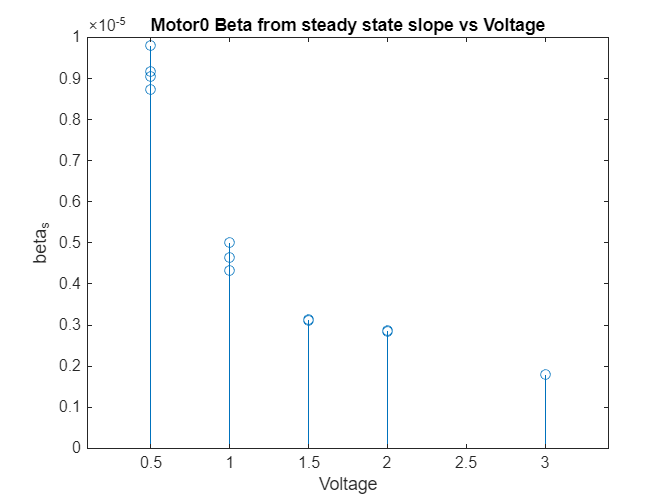

stem(voltages,beta_slope)
title(motorname+"Beta from steady state slope vs Voltage")
xlabel("Voltage")
ylabel("beta_s")

## Discontinuity Analysis

NaNMean(tauDisco)

ans = 0.0505

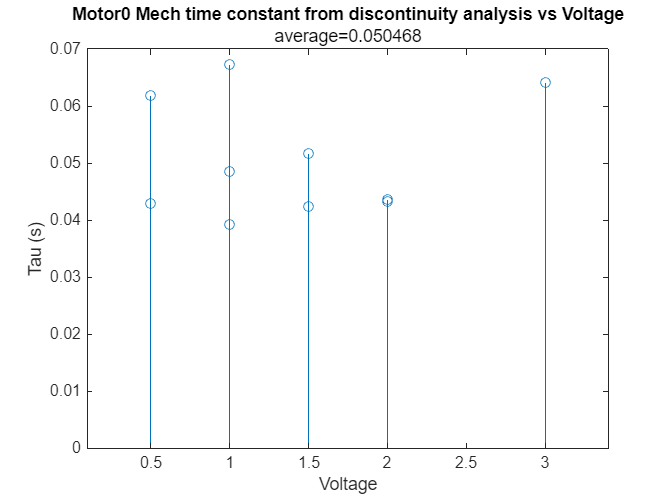

stem(voltages,tauDisco)
title(motorname+"Mech time constant from discontinuity analysis vs Voltage")
xlabel("Voltage")
ylabel("Tau (s)")
subtitle("average="+NaNMean(tauDisco))

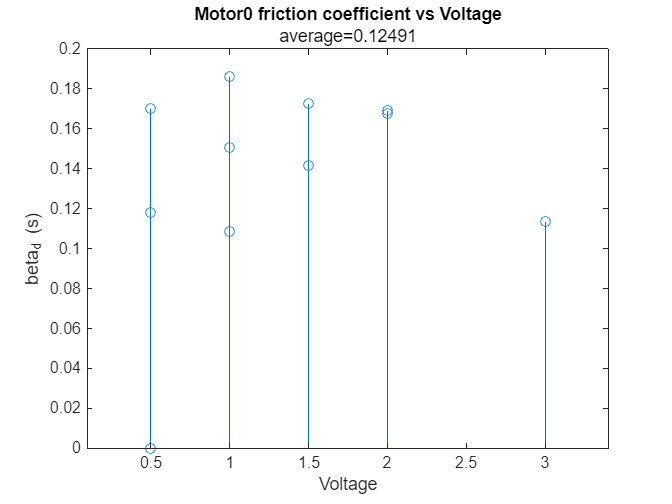


stem(voltages,betaDisco)
title(motorname+"friction coefficient vs Voltage")
xlabel("Voltage")
ylabel("beta_d (s)")

subtitle("average="+NaNMean(betaDisco))


%% it doesn't worl ????
function [beta] = betaFromSteadyStateSpeed(v,omega_l)
    Km = 7.68e-3; % V/(rad/s)
    Ra = 2.6;
    omega_m = omega_l * 70;
    torque = (Km*v -Km^2*omega_m)/Ra;
    % B = v * Km *70 / (omega_l  * Ra);
    beta = torque/omega_m ;%- Km^2/Ra;
end


function [beta] = TransientAnalysis(tau)
    if  isnan(tau)
         B = NaN;
        beta = NaN;
    else
    
        J = 0.007309;
        Ra = 2.6;
        Km = 7.68e-3; % V/(rad/s)
        B = J/tau;
        beta = B - Km^2/Ra;
    end

end

function f = NaNMean(values)
    proper_el = 0;
    sum = 0;
    for i = 1:size(values,2)
        if not(isnan(values(i)))
            proper_el = proper_el+1;
            sum = sum + values(i);

        end
    end
    f = sum/proper_el;
end